# EE3TP3 LAB 4

### PART 1.3

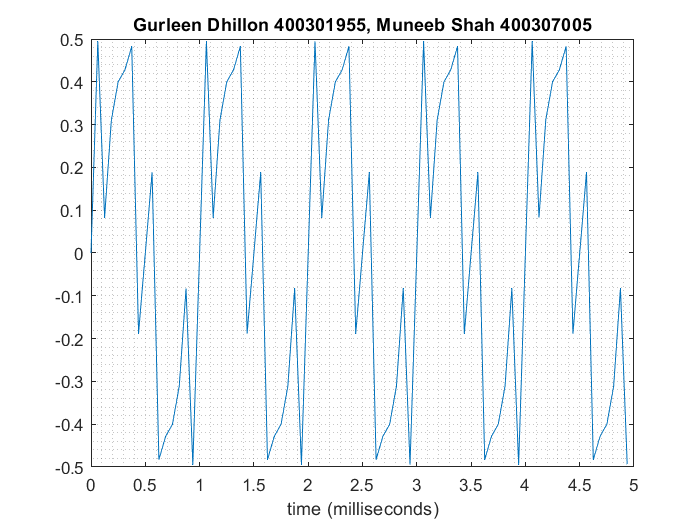

clear
[signal, Fs] = audioread("tones2022.wav"); % Read in the signal from the audio file
L = length(signal);  %Number of samples in the signal
T = 1/Fs; % Sampling period in seconds
t = [0:L-1]*T; % Time vector in seconds

% Plot the signal for t_plot msec
t_plot = 5;
msec_per_sec = 1000;
numSamples = t_plot*Fs/msec_per_sec;
plot(msec_per_sec*t(1:numSamples), signal(1:numSamples))
title('Gurleen Dhillon 400301955, Muneeb Shah 400307005')
xlabel('time (milliseconds)')
grid('minor');

%export graph
exportgraphics(gcf, 'lab4_part1a.jpg');

### PART 1.5

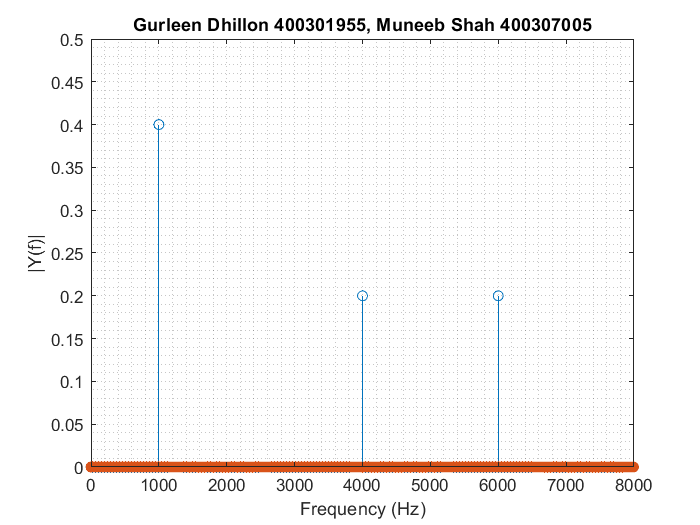

% Take the DFT
Y = fft(signal)/L;
Ys = fftshift(signal)/L;
f = Fs/2*linspace(0,1,L/2+1);

% Plot the single-sided magnitude spectrum.
stem(f,2*abs(Y(1:L/2+1)))
hold on
stem(f,2*abs(Ys(1:L/2+1)))
title ('Gurleen Dhillon 400301955, Muneeb Shah 400307005')
xlabel('Frequency (Hz)')
ylabel('|Y(f)|')
axis([0 Fs/2 0 .5]);
grid('minor');
hold off


%export graph
exportgraphics(gcf, 'lab4_part1b.jpg');

### PART 1.6

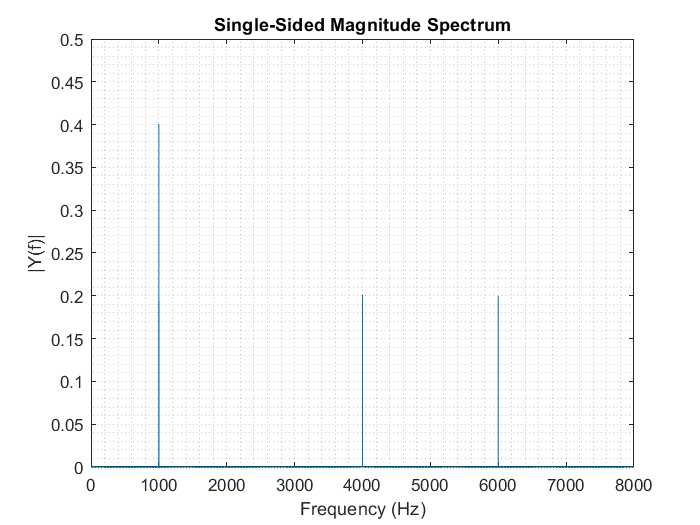

% Plot the single-sided magnitude spectrum.
plot(f,2*abs(Y(1:L/2+1)))
title('Single-Sided Magnitude Spectrum')
xlabel('Frequency (Hz)')
ylabel('|Y(f)|')
axis([0 Fs/2 0 .5]);
grid('minor');

%export graph
exportgraphics(gcf, 'lab4_part1c.jpg');

### PART 1.8

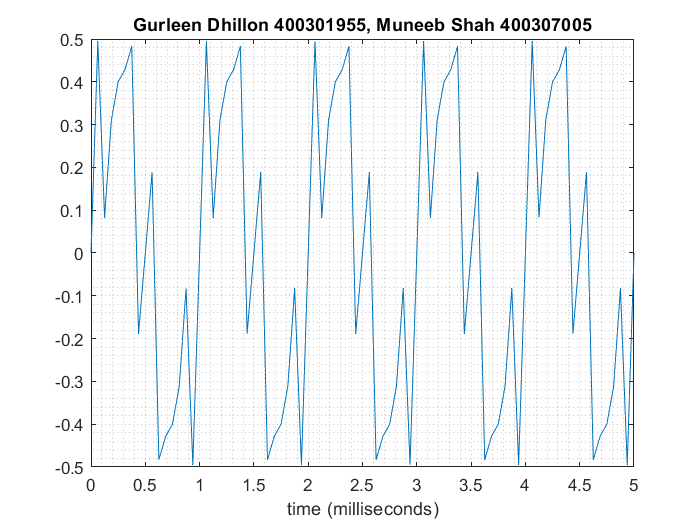

Fs = 16000;
T = 1/Fs; % Sampling period in seconds
t = [0:T*1000:5]; % Time vector in seconds

%create sinusoids with amplitudes and frequencies
sin1 = 0.4*sin(1*2*pi*t);
sin2 = 0.2*sin(4*2*pi*t);
sin3 = 0.2*sin(6*2*pi*t);
sin_total = sin1 + sin2 + sin3;

% Plot the signal for t_plot msec
plot(t, sin_total)
title('Gurleen Dhillon 400301955, Muneeb Shah 400307005')
xlabel('time (milliseconds)')
grid('minor');

%export graph
exportgraphics(gcf, 'lab4_part1d.jpg');

### PART 2.3

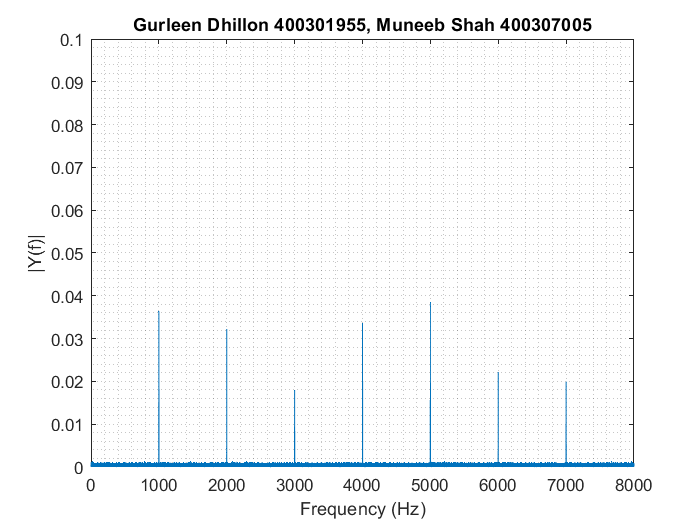

[signal, Fs] = audioread("SecretMessage2022.wav"); % Read in the signal from the audio file
L = length(signal);  %Number of samples in the signal
T = 1/Fs; % Sampling period in seconds

% Take the DFT
Y = fft(signal)/L;
f = Fs/2*linspace(0,1,L/2+1);

% Plot the single-sided magnitude spectrum.
plot(f,2*abs(Y(1:L/2+1)));
title('Gurleen Dhillon 400301955, Muneeb Shah 400307005')
xlabel('Frequency (Hz)')
ylabel('|Y(f)|')
axis([0 Fs/2 0 .1]);
grid('minor');

%export graph
exportgraphics(gcf, 'lab4_part2a.jpg');

### PART 2.4

samples = [28*Fs, 29*Fs];
[signal, Fs] = audioread("SecretMessage2022.wav", samples); % Read in the signal from the audio file
L = length(signal);  %Number of samples in the signal
T = 1/Fs; % Sampling period in seconds

% Take the DFT
Y = fft(signal)/L;
f = Fs/2*linspace(0,1,L/2+1);

% Plot the single-sided magnitude spectrum.
plot(f,2*abs(Y(1:L/2+1)))

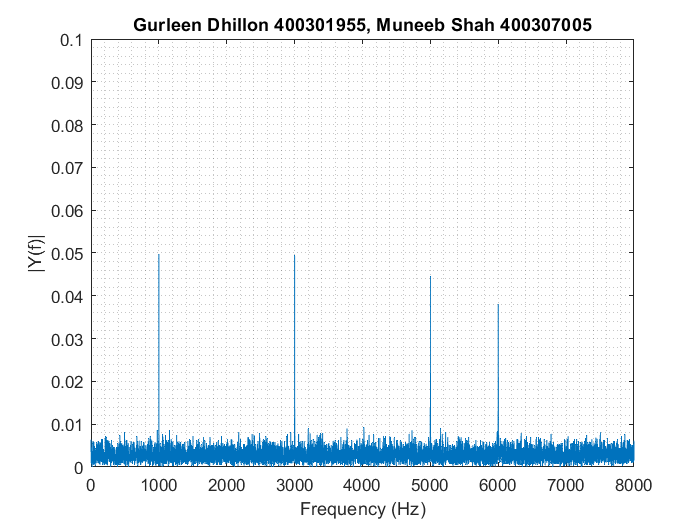

title('Gurleen Dhillon 400301955, Muneeb Shah 400307005')
xlabel('Frequency (Hz)')
ylabel('|Y(f)|')
axis([0 Fs/2 0 .1]);
grid('minor');

%export graph
exportgraphics(gcf, 'lab4_part2DECODE.jpg');